# TCI model

    Liu, J. *et al.* Spin-filtered edge states with an electrically tunable gap in a two-dimensional topological crystalline insulator. *Nature Mater* **13**, 178–183 (2014).  


$$$$
H(k)=\left(v_{x} k_{x} \sigma_{x}-v_{y} k_{y} \sigma_{y}\right) \tau_{x}+m \tau_{z}
$$$$


## TCI model

### Useful matrix

clear;
%% useful tool
s_0   = pauli_matric(0)  ;  s_x = pauli_matric(1);  s_y =  pauli_matric(2) ;  s_z = pauli_matric(3);
sigma_0 = pauli_matric(0);sigma_x =  pauli_matric(1);sigma_y =  pauli_matric(2);sigma_z = pauli_matric(3);
tau_0   = pauli_matric(0);  tau_x =  pauli_matric(1);  tau_y =  pauli_matric(2);  tau_z = pauli_matric(3);

### k·p model

syms v_1 v_2 m real;
syms k_x k_y k_z real;
%
k_plus  = k_x + 1i* k_y;
k_minus = k_x - 1i* k_y;
%
TCI = HK(4,2);
%
TCI = TCI ...
    +Term(v_1*k_x ,sigma_x*tau_x )...
    +Term(v_2*k_y ,sigma_x*tau_y )...
    +Term(m     ,sigma_z*tau_0 )...
    ;

Setting 1/1 term into HK ...


Setting 1/1 term into HK ...


Setting 1/1 term into HK ...


TCI = TCI < 'POSCAR' ;
TCI_sym = sym(TCI)

$$TCI\_sym = \left(\begin{array}{cccc} m & 0 & 0 & -k_{y}\,v_{2}\,\mathrm{i}+k_{x}\,v_{1}\\ 0 & m & k_{y}\,v_{2}\,\mathrm{i}+k_{x}\,v_{1} & 0\\ 0 & -k_{y}\,v_{2}\,\mathrm{i}+k_{x}\,v_{1} & -m & 0\\ k_{y}\,v_{2}\,\mathrm{i}+k_{x}\,v_{1} & 0 & 0 & -m \end{array}\right)$$

Mz = Oper.mirror([0,0,1],double(-1i*sigma_z*tau_z));
MzU = sym(Mz.U)

$$MzU = \left(\begin{array}{cccc} -\mathrm{i} & 0 & 0 & 0\\ 0 & \mathrm{i} & 0 & 0\\ 0 & 0 & \mathrm{i} & 0\\ 0 & 0 & 0 & -\mathrm{i} \end{array}\right)$$

[A,U_Mz] = eig(MzU);

A\TCI_sym*A

$$ans = \left(\begin{array}{cccc} m & -k_{y}\,v_{2}\,\mathrm{i}+k_{x}\,v_{1} & 0 & 0\\ k_{y}\,v_{2}\,\mathrm{i}+k_{x}\,v_{1} & -m & 0 & 0\\ 0 & 0 & m & k_{y}\,v_{2}\,\mathrm{i}+k_{x}\,v_{1}\\ 0 & 0 & -k_{y}\,v_{2}\,\mathrm{i}+k_{x}\,v_{1} & -m \end{array}\right)$$

TCI_pi = TCI.reseq([2,3]);
TCI_pi.sym

$$ans = \left(\begin{array}{cc} m & k_{y}\,v_{2}\,\mathrm{i}+k_{x}\,v_{1}\\ -k_{y}\,v_{2}\,\mathrm{i}+k_{x}\,v_{1} & -m \end{array}\right)$$

TCI_mi = TCI.reseq([1,4]);
TCI_mi.sym

$$ans = \left(\begin{array}{cc} m & -k_{y}\,v_{2}\,\mathrm{i}+k_{x}\,v_{1}\\ k_{y}\,v_{2}\,\mathrm{i}+k_{x}\,v_{1} & -m \end{array}\right)$$

para

v_1 = 1;
v_2 = 1;
m =  1;

### kp2TB

TCI_TB = TCI.kp2TB();
TCI_TB_pi= TCI_pi.kp2TB();
TCI_TB_mi= TCI_mi.kp2TB();
%
%
TCI_TB_n = TCI_TB.Subsall();
TCI_TB_pi_n = TCI_TB_pi.Subsall();
TCI_TB_mi_n = TCI_TB_mi.Subsall();

%%
TCI_TB_n = TCI_TB_n <'KPOINTS';

% bulk
EIGENCAR = TCI_TB_n.EIGENCAR_gen();

BAND calculating 180/180 ...


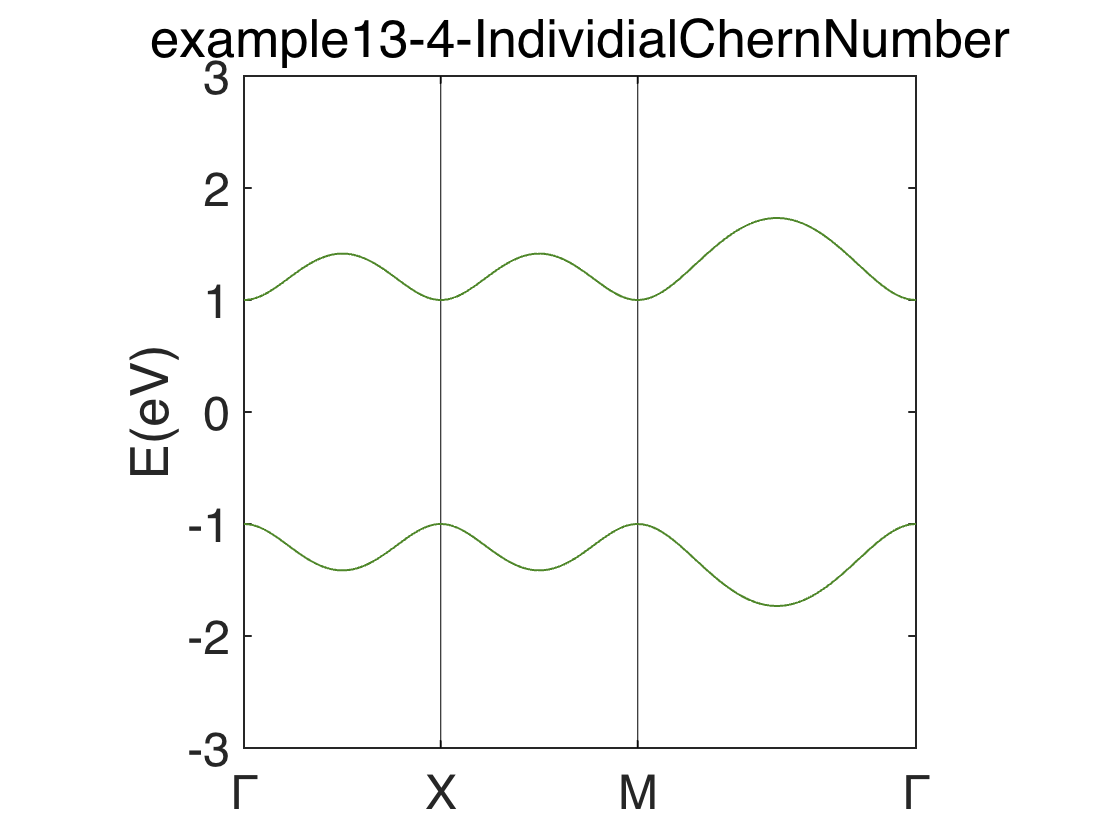

bandplot(EIGENCAR,[-3,3]);

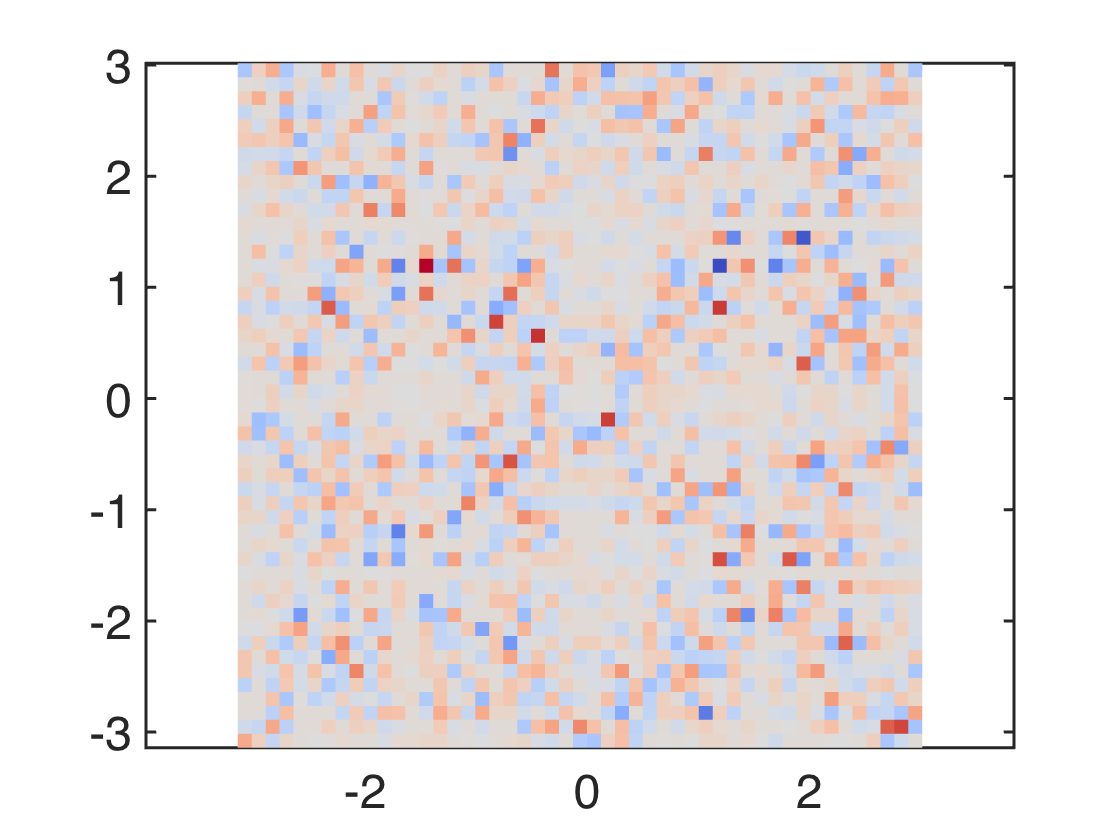

[BCCAR,Kgrid]= TCI_TB_n.BC_2D();
vasplib.BCplot2D(BCCAR,Kgrid);

sum(BCCAR,'all')/(2*pi)

ans = -2.2391e-17

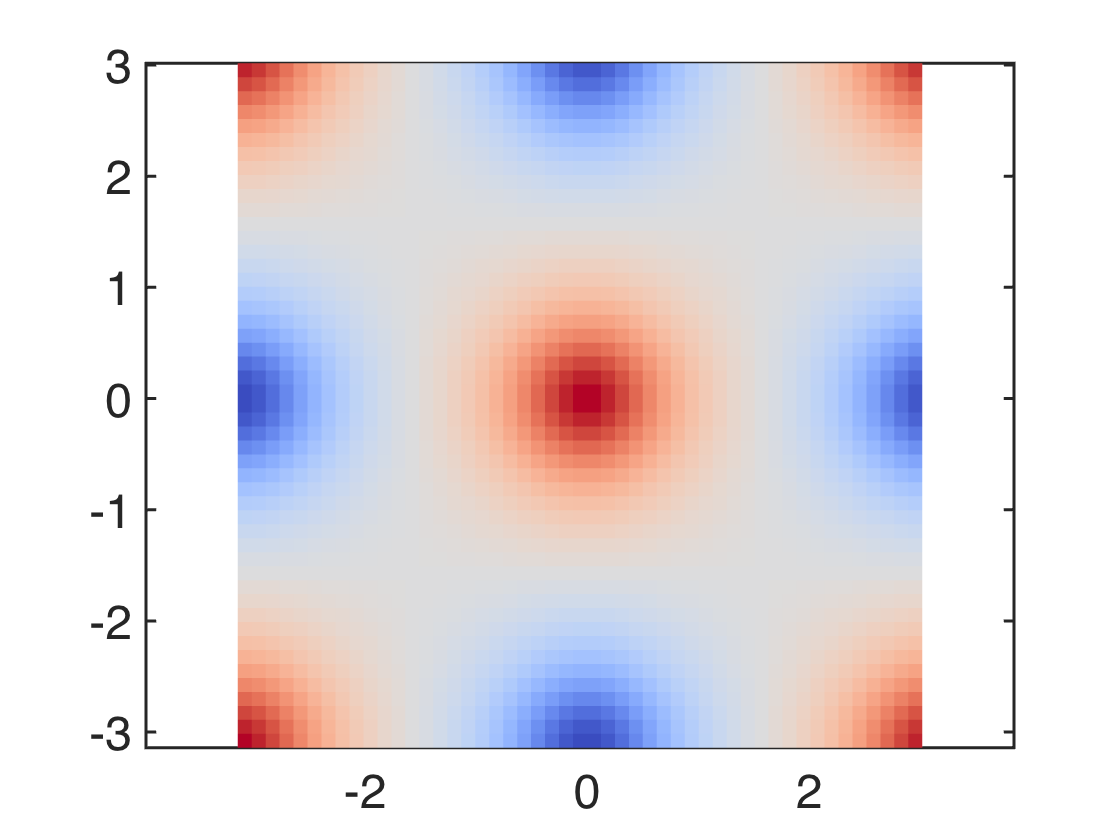

[BCCAR,Kgrid] = TCI_TB_pi_n.BC_2D();
vasplib.BCplot2D(BCCAR,Kgrid);

sum(BCCAR,'all')/(2*pi)

ans = 4.1413e-19

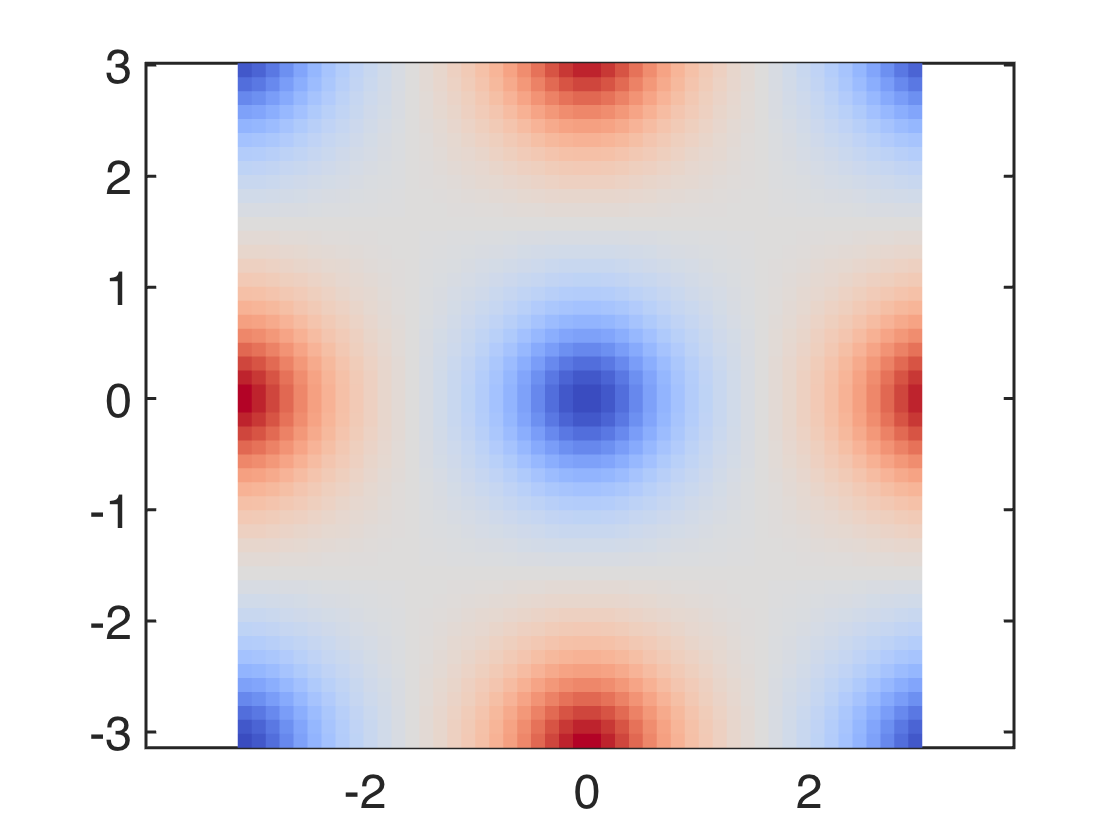

[BCCAR,Kgrid] = TCI_TB_mi_n.BC_2D();
vasplib.BCplot2D(BCCAR,Kgrid);

sum(BCCAR,'all')/(2*pi)

ans = -4.1413e-19